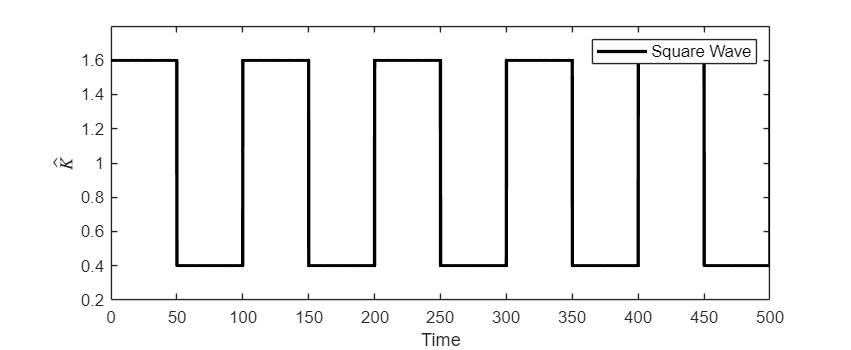

% This script simulates the deterministic population dynamics of susceptible
% bacteria (B), infected bacteria (I), and bacteriophages (P) using a system
% of ordinary differential equations (ODEs).
%
% It compares how two different types of time-varying environmental carrying
% capacity (K) influence the system:
%   1. Square wave fluctuations
%   2. Sine wave fluctuations
% ========================================================================

clear; clc; close all;

%% Parameter Settings
A = 0.6; f = 0.01; r = 1.0;
K0 = 1; a = 0.09; Omega = 50;
alpha = 2; delta = 0.04;
tspan = [0, 500];
y0 = [0.1; 0.3; 0.1]; 

options = odeset('MaxStep', 1e-3, 'RelTol', 1e-10, 'AbsTol', 1e-8);

%% 1. Solve Square-Wave Driven System
[t_sq, y_sq] = ode15s(@(t,y) fluctuate_1B_fangbo(t, y, A, f, r, K0, a, Omega, alpha, delta), ...
                        tspan, y0, options);

%% 2. Solve Sine-Wave Driven System
[t_sn, y_sn] = ode15s(@(t,y) fluctuate_1B_sine(t, y, A, f, r, K0, a, Omega, alpha, delta), ...
                        tspan, y0, options);

%% Extract State Variables
B_sq = y_sq(:,1); I_sq = y_sq(:,2); P_sq = y_sq(:,3);
B_sn = y_sn(:,1); I_sn = y_sn(:,2); P_sn = y_sn(:,3);

%% Generate Uniform Time Axis for Smooth K Comparison (Avoids Uneven Sampling from Adaptive Step Size)
t_plot = linspace(0, 500, 5000);
K_sq_plot = K0 * (1 + A * (2*(mod(f*t_plot, 1) < 0.5) - 1));
K_sn_plot = K0 * (1 + A * sin(2*pi*f*t_plot));

%% ================= Plotting Section =================

% Figure 1: Square Wave K Profile
figure('Position', [100, 100, 850, 350]);
plot(t_plot, K_sq_plot, 'k-', 'LineWidth', 2);
xlabel('Time'); 
ylabel('$\hat{K}$','Interpreter', 'latex');
ylim([K0*(1-A)-0.2, K0*(1+A)+0.2]);
legend('Square Wave', 'Location', 'northeast', 'FontSize', 10);
grid off; box on;

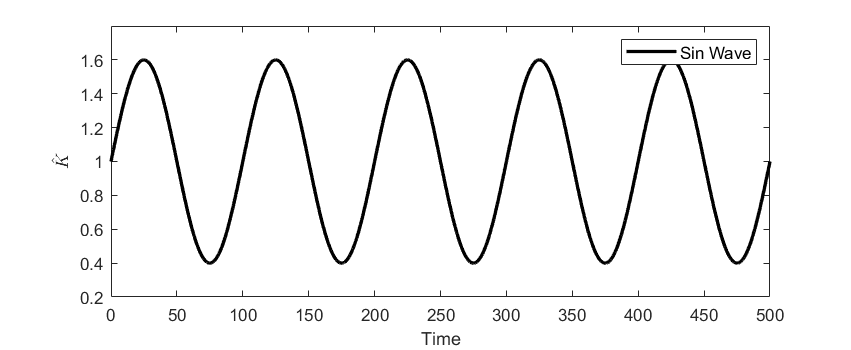


% Figure 1b: Sine Wave K Profile
figure('Position', [100, 100, 850, 350]);
plot(t_plot, K_sn_plot, 'k-', 'LineWidth', 2);
xlabel('Time'); ylabel('$\hat{K}$','Interpreter', 'latex');
legend('Sin Wave', 'Location', 'northeast', 'FontSize', 10);
ylim([K0*(1-A)-0.2, K0*(1+A)+0.2]);
grid off; box on;

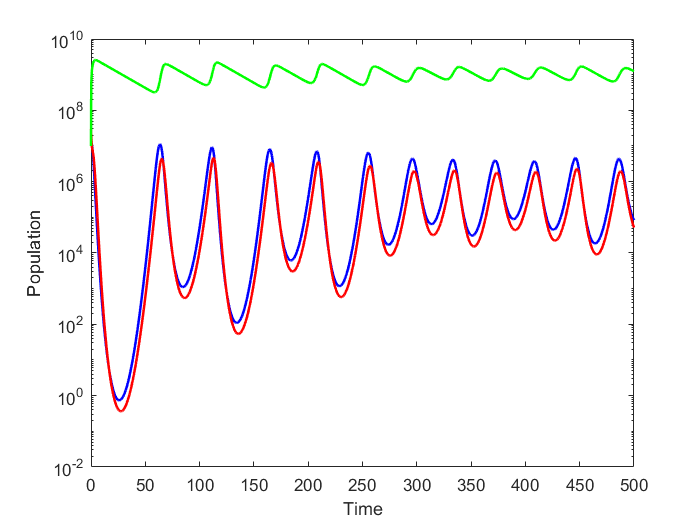


% Figure 2: B-I-P Time Series under Square-Wave Forcing
figure;
plot(t_sq, B_sq*10^8, 'b-', 'LineWidth', 1.5); hold on;
plot(t_sq, I_sq*10^8, 'r-', 'LineWidth', 1.5);
plot(t_sq, P_sq*10^8, 'g-', 'LineWidth', 1.5);
xlabel('Time'); 
ylabel('Population');
set(gca, 'yscale', 'log');
%legend({'B', 'I', 'P'}, 'Location', 'northeast', 'FontSize', 10);
grid off; box on;

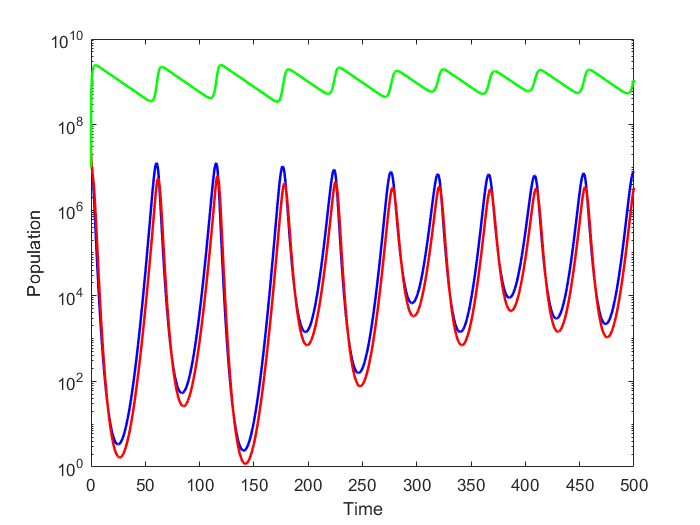


% Figure 3: B-I-P Time Series under Sine-Wave Forcing
figure;
plot(t_sn, B_sn*10^8, 'b-', 'LineWidth', 1.5); hold on;
plot(t_sn, I_sn*10^8, 'r-', 'LineWidth', 1.5);
plot(t_sn, P_sn*10^8, 'g-', 'LineWidth', 1.5);
xlabel('Time'); 
ylabel('Population');
set(gca, 'yscale', 'log');
%legend({'B', 'I', 'P'}, 'Location', 'northeast', 'FontSize', 10);
grid off; box on;



%% ================= ODE Function Definitions =================


function dydt = fluctuate_1B_fangbo(t, y, A, f, r, K0, a, Omega, alpha, delta)
    B = y(1); I = y(2); P = y(3);
    % Square wave K: alternates between K0*(1+A) and K0*(1-A)
    K = K0 * (1 + A * (2*(mod(f*t, 1) < 0.5) - 1));
    
    N = sum(I) + sum(B);
    dBdt = r .* (1 - N/K) .* B - a .* B .* P;
    dIdt = a .* B .* P - alpha .* I;
    
    sum_bI = alpha * sum(I);
    sum_aB = sum(a .* B) * P;
    dPdt = Omega * sum_bI - sum_aB - delta * P;
    
    dydt = [dBdt; dIdt; dPdt];
end

function dydt = fluctuate_1B_sine(t, y, A, f, r, K0, a, Omega, alpha, delta)
    B = y(1); I = y(2); P = y(3);
    % Sine-wave K: Mean K0, amplitude K0*A, kept consistent with the square wave
    K = K0 * (1 + A * sin(2*pi*f*t));
    
    N = sum(I) + sum(B);
    dBdt = r .* (1 - N/K) .* B - a .* B .* P;
    dIdt = a .* B .* P - alpha .* I;
    
    sum_bI = alpha * sum(I);
    sum_aB = sum(a .* B) * P;
    dPdt = Omega * sum_bI - sum_aB - delta * P;
    
    dydt = [dBdt; dIdt; dPdt];
end